Matlab code for the Course: **Modelling and Simulation Mechatronics System (2020)**

by Enrico Bertolazzi and Francesco Biral

Dipartimento di Ingegneria Industriale

Università degli Studi di Trento

email: [enrico.bertolazzi@unitn.it](mailto:enrico.bertolazzi@unitn.it)

#### Initialize by cleaning memory and widows

close all;

#### Initialize parameters of the model and instantiate model class

mass    = 1;
gravity = 9.81;
ell     = 1;
DAE     = WinxDAE( mass, gravity, ell );

#### Initialize the solver class

solver = DAE3TaylorSolver();
solver.setDAE( DAE );

#### Initialize the range where solution is computed and initial conditions

T     = 90;
DT    = 0.01;
theta = pi/2;
alpha = pi/2;

x     = ell*sin(theta)*cos(alpha);
y     = ell*sin(theta)*sin(alpha);
z     = ell*cos(theta);
vx    = 0;
vy    = 0;
vz    = 0;

s = 50;
theta1 =pi/2;
theta2 = 0.8611263415;   %theta2 =2.750353614;
theta4 = 0.5935894893;   %theta4 = 3.134812320;
theta5 = 0;
theta6 = 0;
s__dot =0;
theta1__dot = 0;
theta2__dot = 0;
theta4__dot =0;
theta5__dot = 0;
theta6__dot = 0;
p0    = [ s, theta1, theta2, theta4, theta5, theta6 ];
v0    = [ s__dot, theta1__dot, theta2__dot, theta4__dot, theta5__dot, theta6__dot ];

#### Advance the DAE (using not stabilized index-1 DAE)

tt  = 0:DT:T;
%tt1 = 0:DT/2:T;
%tt2 = 0:DT/10:T;
[p, v]  = solver.advance_simple( tt,  p0, v0 );
%[p1,v1] = solver.advance_simple( tt1, p0, v0 );
%[p2,v2] = solver.advance_simple( tt2, p0, v0 );

#### plot solution

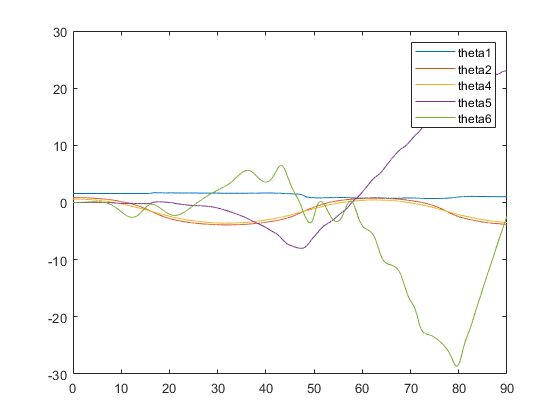

figure();
plot(tt,p(2,:),tt,p(3,:),tt,p(4,:),tt,p(5,:),tt,p(6,:)); 
legend('theta1', 'theta2','theta4','theta5','theta6'); 

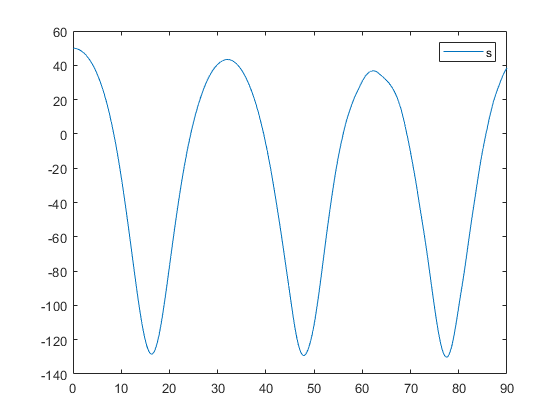

plot(tt,p(1,:)); 
legend('s'); % s in another chart because the scale it's too different

#### Advance the DAE (using  stabilized index-1 DAE)

set parameter

eta   = 0.5;
omega = 4;

advance

tt  = 0:DT:T;
tt1 = 0:DT/2:T;
tt2 = 0:DT/10:T;
[p, v ] = solver.advance_Baumgarte( tt,  p0, v0, eta, omega );
[p1,v1] = solver.advance_Baumgarte( tt1, p0, v0, eta, omega );
[p2,v2] = solver.advance_Baumgarte( tt2, p0, v0, eta, omega );

#### plot solution

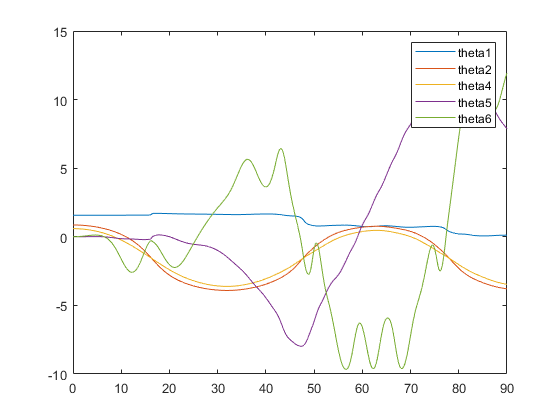

figure();
plot(tt2,p2(2,:),tt2,p2(3,:),tt2,p2(4,:),tt2,p2(5,:),tt2,p2(6,:)); 
legend('theta1', 'theta2','theta4','theta5','theta6'); 

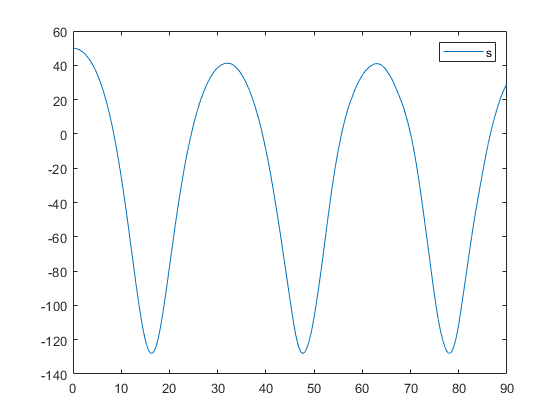

plot(tt2,p2(1,:)); 
legend('s'); % s in another chart because the scale it's too different